# CHAPTER 1 - Starting with Matlab

## Command Window

- Comment with % 

- Suppress outputs with ; 

- Clear command window with clc

## Display Formats

- Default is short (4 dp) 

- Change with format command 

format short % 4 dp
format long % 15 dp
format short e % 4 dp, scientific notation
format bank % 2 dp
format compact % no empty lines
format loose % adds empty lines

## Commands to Manage Variables

- clear - removes all variables from memory 

- clear x y z - removes x y z specifically 

- who - displays list of variables currently in memory 

- whos - displays list of variables and their metadata

# CHAPTER 2 - Creating Arrays

## 1D Arrays

- Row vectors are separated by spaces or commas

- Column vectors are separated by semi-colons or by pressing enter

#### Code

- row_vector = [first:spacing:last] 

- row_vector = first:spacing:last

- --> spacing is default 1 if omitted

row_vector = 1:10

row_vector =           1.00          2.00          3.00          4.00          5.00          6.00          7.00          8.00          9.00         10.00


- row_vector = linspace(first, last, # elements)

- --> # elements default is 100

row_vector_lin = linspace(1, 10)

row_vector_lin =           1.00          1.09          1.18          1.27          1.36          1.45          1.55          1.64          1.73          1.82          1.91          2.00          2.09          2.18          2.27          2.36          2.45          2.55          2.64          2.73          2.82          2.91          3.00          3.09          3.18          3.27          3.36          3.45          3.55          3.64          3.73          3.82          3.91          4.00          4.09          4.18          4.27          4.36          4.45          4.55          4.64          4.73          4.82          4.91          5.00          5.09          5.18          5.27          5.36          5.45


## 2D Arrays

- Creating a 2D array

- --> row vectors, separated by ;

matrix = [1 2 3; 4 5 6; 7 8 9]

matrix =           1.00          2.00          3.00
          4.00          5.00          6.00
          7.00          8.00          9.00


#### Commands

- zeros(m, n) - zero matrix

- ones(m, n) - ones matrix

- eye(n) - identity matrix

- --> m = row, n = column

zeros(3, 3)

ans =              0             0             0
             0             0             0
             0             0             0


ones(3, 3)

ans =           1.00          1.00          1.00
          1.00          1.00          1.00
          1.00          1.00          1.00


eye(3)

ans =           1.00             0             0
             0          1.00             0
             0             0          1.00


## Transpose

- apply ' after variable

- --> switches rows and columns in matrices

row_vector'

ans =           1.00
          2.00
          3.00
          4.00
          5.00
          6.00
          7.00
          8.00
          9.00
         10.00


matrix'

ans =           1.00          4.00          7.00
          2.00          5.00          8.00
          3.00          6.00          9.00


## Array Addressing

- Elements can be addressed individually or in subgroups

#### Vector

- the address of an element in a vector is its position in the row (or column)

- --> 1-indexing

row_vector(1)

ans =           1.00


row_vector(2)

ans =           2.00


- can use to change the value of an element of a vector

row_vector(1) = 0

row_vector =              0          2.00          3.00          4.00          5.00          6.00          7.00          8.00          9.00         10.00


row_vector(1) = 1

row_vector =           1.00          2.00          3.00          4.00          5.00          6.00          7.00          8.00          9.00         10.00


#### Matrix

- the address of an element in a matrix is its position, defined by the row number and column number

matrix(1, 1)

ans =           1.00


### Using a Colon (:)

#### Vector

- ve(:) refers to all the elements of the vector ve

- va(m:n) refers to elements m through n (inclusive)

row_vector

row_vector =           1.00          2.00          3.00          4.00          5.00          6.00          7.00          8.00          9.00         10.00


row_vector(:)

ans =           1.00
          2.00
          3.00
          4.00
          5.00
          6.00
          7.00
          8.00
          9.00
         10.00


row_vector(1:5)

ans =           1.00          2.00          3.00          4.00          5.00


#### Matrix

- ma(m:n, p:q) refers to rows m through n and columns p through q

matrix(1:2, 2:3)

ans =           2.00          3.00
          5.00          6.00


- new vectors and matrices can be created from existing ones using array addressing

v = [4:3:34]

v =           4.00          7.00         10.00         13.00         16.00         19.00         22.00         25.00         28.00         31.00         34.00


u = v([3, 5, 7:10])

u =          10.00         16.00         22.00         25.00         28.00         31.00


A = [10:-1:4; ones(1, 7); 2:2:14; zeros(1, 7)]

A =          10.00          9.00          8.00          7.00          6.00          5.00          4.00
          1.00          1.00          1.00          1.00          1.00          1.00          1.00
          2.00          4.00          6.00          8.00         10.00         12.00         14.00
             0             0             0             0             0             0             0


B = A([1, 3], [1, 3, 5:7])

B =          10.00          8.00          6.00          5.00          4.00
          2.00          6.00         10.00         12.00         14.00


### Adding Elements to Existing Variable

#### Vector

- elements can be added by assigning values to the new elements

- --> Matlab will insert zeros between the last original elements and the new element

v = 1:5

v =           1.00          2.00          3.00          4.00          5.00


v(6) = 0

v =           1.00          2.00          3.00          4.00          5.00             0


v(10) = 9

v =           1.00          2.00          3.00          4.00          5.00             0             0             0             0          9.00


- can also append existing vectors

RE = [3 8 1 24]

RE =           3.00          8.00          1.00         24.00


GT = [4:3:16]

GT =           4.00          7.00         10.00         13.00         16.00


KNH = [RE GT]

KNH =           3.00          8.00          1.00         24.00          4.00          7.00         10.00         13.00         16.00


KNV = [RE'; GT']

KNV =           3.00
          8.00
          1.00
         24.00
          4.00
          7.00
         10.00
         13.00
         16.00


#### Matrix

- can assign new values to new rows or columns

- --> need to be careful, size of new rows and columns need to fit existing matrix

- --> Matlab increases the size of the matrix and fills it with zeros if a new value is assigned to an element beyond the current dimensions

matrix

matrix =           1.00          2.00          3.00
          4.00          5.00          6.00
          7.00          8.00          9.00


matrix(1, 6) = 5

matrix =           1.00          2.00          3.00             0             0          5.00
          4.00          5.00          6.00             0             0             0
          7.00          8.00          9.00             0             0             0


## Deleting Elements

- assign nothing to an existing variable using []

v

v =           1.00          2.00          3.00          4.00          5.00             0             0             0             0          9.00


v(6:10) = []

v =           1.00          2.00          3.00          4.00          5.00


## Built-in Functions

- length(A) - returns number of elements in vector A

- size(A) - returns a row vector [m, n], where m and n are the size m x n of the array A

- reshape(A, m, n) - creates an m x n matrix from the elements of matrix A

- --> the elements are taken column after column

- --> matrix A must have m * n elements

- diag(v) - when v is a vector, creates a square matric with the elements of v in the diagonal

- diag(A) - when A is a square matrix, creates a vector from the diagonal elements of A

## Strings

- typed between single quotes (') and can be assigned to variables

- --> stored in an array, like numbers where each character is an element

- --> vector operations work (re-assigning, deleting)

- can also be stored in a matrix

- --> all rows must have the same number of elements

- --> issue when dealing with specific wordings

- --> all rows can be made equal by adding spaces by using char

info = char('Student Name:', 'John Smith', 'Grade:', 'A+')

info = 4×13 char array
    'Student Name:'
    'John Smith   '
    'Grade:       '
    'A+           '


# CHAPTER 3 - Mathematical Operations with Arrays

## Addition and Subtraction

- +- can be used to add arrays of identizal size and to add a scalar to an array

matrix + matrix

ans =           2.00          4.00          6.00             0             0         10.00
          8.00         10.00         12.00             0             0             0
         14.00         16.00         18.00             0             0             0


matrix + 5

ans =           6.00          7.00          8.00          5.00          5.00         10.00
          9.00         10.00         11.00          5.00          5.00          5.00
         12.00         13.00         14.00          5.00          5.00          5.00


## Array Multiplication

- * executed according to the rules of linear algebra

- --> for two arrays, it computes the dot product

- --> the power operator only works on square matrices

- --> not commutative (order matters!)

- two vectors can be multiplied only if they have the same number of element and if they're a row-column vector pair

- --> there also exists a built-in function, dot(a, b)

v * v'

ans =          55.00


dot(v, v')

ans =          55.00


- can also multiply scalars to arrays

v * 5

ans =           5.00         10.00         15.00         20.00         25.00


## Inverse

- inv(A) or by raising the matrix to the power of -1

- exists if and only if the determinant is non-zero

## Determinants

- det(A)

## Array Division

- also associated with the rules of linear algebra

- two types

- --> right division

- --> left division

#### Left Division (\)

- used to solve the matrix equation AX = B

- --> X and B are column vectors

B = [4; 4; 4; 4]

B =           4.00
          4.00
          4.00
          4.00


X = A\B

X =           0.33
             0
             0
             0
             0
             0
          0.25


#### Right Division(/)

- used to solve XC = D

- --> X and D are row vectors

C = A

C =          10.00          9.00          8.00          7.00          6.00          5.00          4.00
          1.00          1.00          1.00          1.00          1.00          1.00          1.00
          2.00          4.00          6.00          8.00         10.00         12.00         14.00
             0             0             0             0             0             0             0


D = [4 4 4 4 4 4 4]

D =           4.00          4.00          4.00          4.00          4.00          4.00          4.00


X = D/C

X =           0.36             0          0.18             0


## Element by Element Operations

- can only be done with arrays of the same size

- --> for operations that follow the rules of linear algebra, type a period in front of the operator to indicate EBE

A .* A

ans =         100.00         81.00         64.00         49.00         36.00         25.00         16.00
          1.00          1.00          1.00          1.00          1.00          1.00          1.00
          4.00         16.00         36.00         64.00        100.00        144.00        196.00
             0             0             0             0             0             0             0


A.^A

ans =  10000000000.00  387420489.00   16777216.00     823543.00      46656.00       3125.00        256.00
          1.00          1.00          1.00          1.00          1.00          1.00          1.00
          4.00        256.00      46656.00   16777216.00 10000000000.00 8916100448256.00 11112006825558016.00
          1.00          1.00          1.00          1.00          1.00          1.00          1.00


A./A

ans =           1.00          1.00          1.00          1.00          1.00          1.00          1.00
          1.00          1.00          1.00          1.00          1.00          1.00          1.00
          1.00          1.00          1.00          1.00          1.00          1.00          1.00
           NaN           NaN           NaN           NaN           NaN           NaN           NaN


A.\A

ans =           1.00          1.00          1.00          1.00          1.00          1.00          1.00
          1.00          1.00          1.00          1.00          1.00          1.00          1.00
          1.00          1.00          1.00          1.00          1.00          1.00          1.00
           NaN           NaN           NaN           NaN           NaN           NaN           NaN


## Random Number Generation

#### The rand Command

- generates uniformly distributed random numbers with values between 0 and 1

rand % single random number

ans =           0.81


rand(2, 2) % mxn matrix

ans =           0.91          0.91
          0.13          0.63


rand(2) %nxn matrix

ans =           0.10          0.55
          0.28          0.96


randperm(5) % row vector, no repeated values of 1 through n

ans =           2.00          5.00          4.00          1.00          3.00


- for random numbers distributed in a range (a, b)

- --> (b - a) * rand + a

#### The randi Command

- generates a uniformly distributed random integer

randi(5) % between 1 and p

ans =           5.00


randi(5, 2) % nxn matrix between 1 and p

ans =           1.00          5.00
          3.00          4.00


randi(5, 2, 2) % mxn matrix between 1 and p

ans =           5.00          1.00
          4.00          5.00


randi([3, 5]) % use [] to set range

ans =           5.00


#### The randn Command

- generates normally distributed numbers with mean 0 and standard deviation of 1

- --> to change std, multiply by std

- --> to change mean, add mean to randn

randn(2, 2) % mxn matrix

ans =           0.49          0.73
          1.03         -0.30


# CHAPTER 4 - Using Script Files and Managing Data

## Data Input

- use input command to allow user to assign values to variables

userinput = input('Type a number: ')

userinput =           5.00


str_input = input('Type a string: ', 's') % to type a string without quotes

str_input = 'hello'

## Data Output

#### The disp Command

# CHAPTER 5 - Two-Dimensional Plots

## The plot Command

- plot(x, y) - where x and y are vectors of the same size

- can include parameters to specify colour and type of marker

- plot(X, y, 'line_specifiers', 'PropertyName', 'PropertyValue')

X = linspace(1, 10)

X =           1.00          1.09          1.18          1.27          1.36          1.45          1.55          1.64          1.73          1.82          1.91          2.00          2.09          2.18          2.27          2.36          2.45          2.55          2.64          2.73          2.82          2.91          3.00          3.09          3.18          3.27          3.36          3.45          3.55          3.64          3.73          3.82          3.91          4.00          4.09          4.18          4.27          4.36          4.45          4.55          4.64          4.73          4.82          4.91          5.00          5.09          5.18          5.27          5.36          5.45


y = sin(X)

y =           0.84          0.89          0.93          0.96          0.98          0.99          1.00          1.00          0.99          0.97          0.94          0.91          0.87          0.82          0.76          0.70          0.63          0.56          0.48          0.40          0.32          0.23          0.14          0.05         -0.04         -0.13         -0.22         -0.31         -0.39         -0.47         -0.55         -0.63         -0.69         -0.76         -0.81         -0.86         -0.90         -0.94         -0.97         -0.99         -1.00         -1.00         -0.99         -0.98         -0.96         -0.93         -0.89         -0.85         -0.80         -0.74


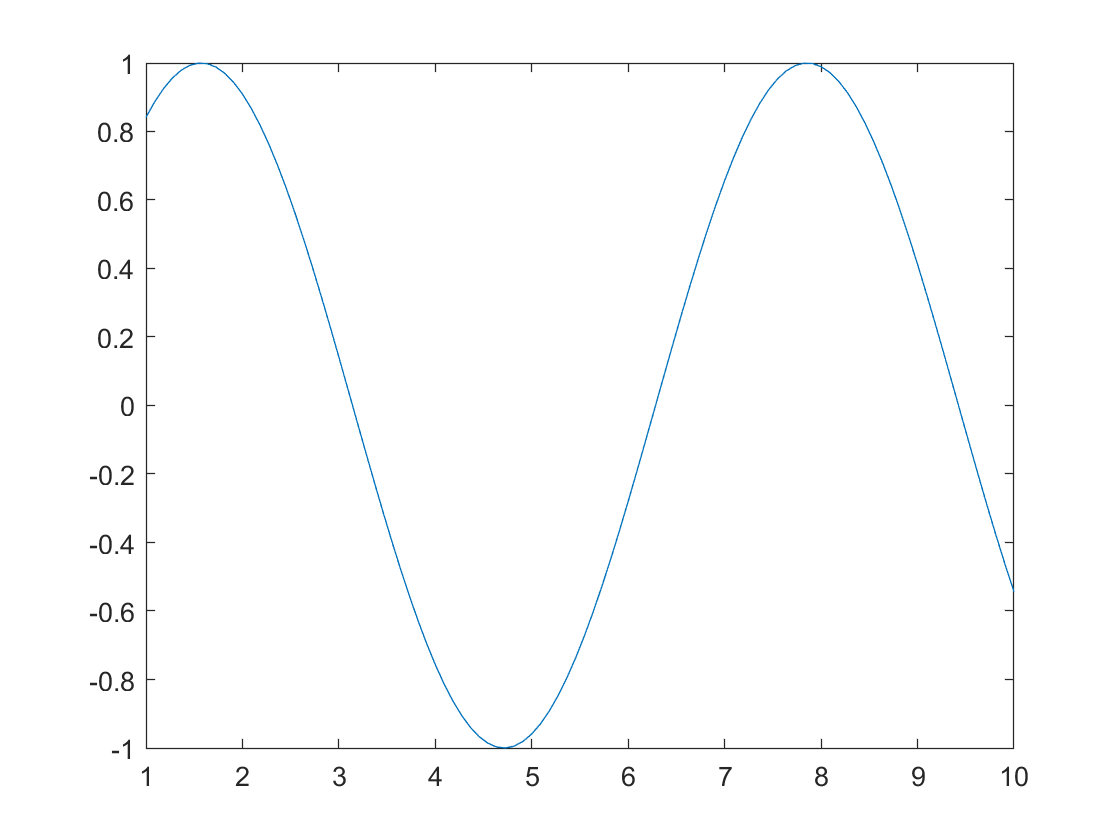

plot(X, y)

### Line Specifiers

- used to define the style and colour of the line and the type of markers

#### Line Style

- solid (default) -> -

- dashed -> --

- dotted -> :

- dash-dot -> -.

#### Line Colour

- red -> r

- green -> g

- blue -> b

- cyan -> c

- magenta -> m

- yellow -> y

- black -> k

- white -> w

#### Marker Type

## The fplot Command

-  plots a function with the form y = f(x) between specified limits

- fplot('function', [min, max], 'line_specifiers')

- --> function typed as a string, can include any letter as independent variable but cannot include any previously defined functions

- --> limits, a vector either with two elements [xmin, xmax] or four elements [xmin, xmax, ymin, ymax]

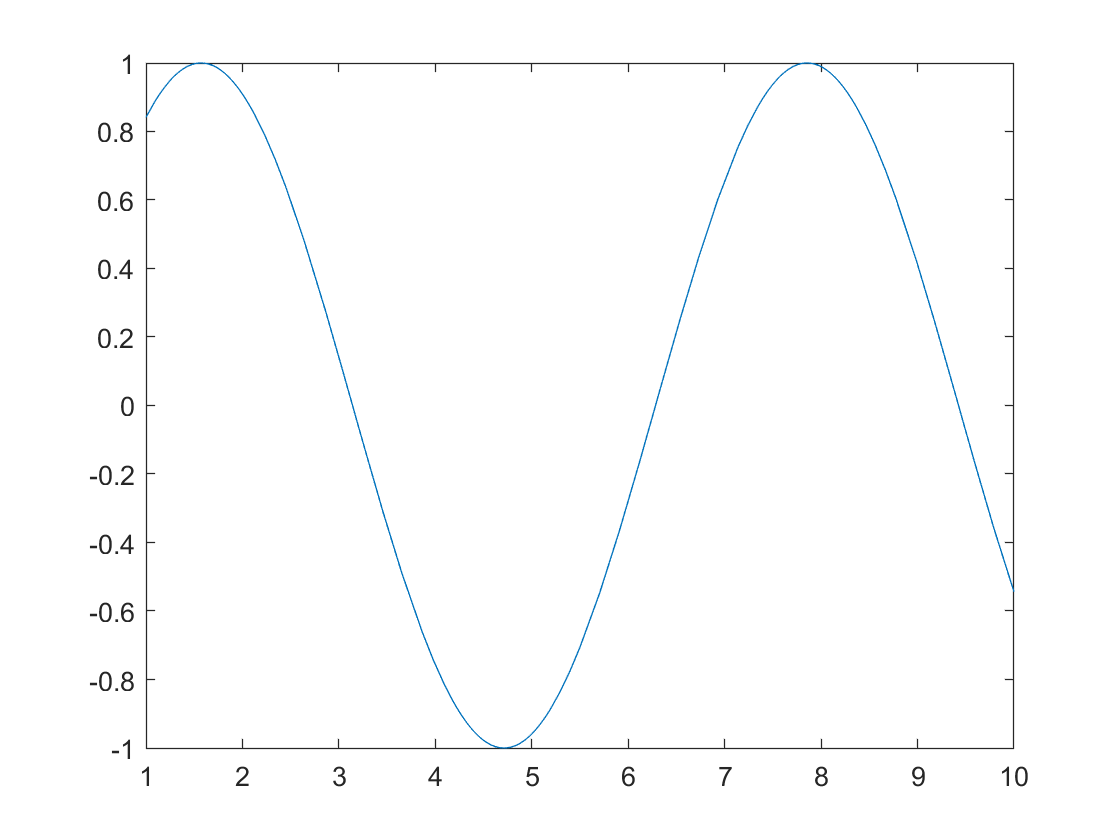

fplot('sin(x)', [1, 10])

## Plotting Multiple Graphs in the Same Plot

- three methods

### Using the plot Command

- plot(x, y, u, v, t, h) creates three graphs (x vs y, u vs v, t vs h) in the same plot

- --> following each pair of vectors are the line and style specifiers

y = sin(X)

y =           0.84          0.89          0.93          0.96          0.98          0.99          1.00          1.00          0.99          0.97          0.94          0.91          0.87          0.82          0.76          0.70          0.63          0.56          0.48          0.40          0.32          0.23          0.14          0.05         -0.04         -0.13         -0.22         -0.31         -0.39         -0.47         -0.55         -0.63         -0.69         -0.76         -0.81         -0.86         -0.90         -0.94         -0.97         -0.99         -1.00         -1.00         -0.99         -0.98         -0.96         -0.93         -0.89         -0.85         -0.80         -0.74


w = cos(X)

w =           0.54          0.46          0.38          0.29          0.21          0.12          0.03         -0.07         -0.16         -0.24         -0.33         -0.42         -0.50         -0.57         -0.65         -0.71         -0.77         -0.83         -0.88         -0.92         -0.95         -0.97         -0.99         -1.00         -1.00         -0.99         -0.98         -0.95         -0.92         -0.88         -0.83         -0.78         -0.72         -0.65         -0.58         -0.51         -0.43         -0.34         -0.25         -0.17         -0.08          0.01          0.11          0.20          0.28          0.37          0.45          0.53          0.61          0.68


z = sin(X) + cos(X)

z =           1.38          1.35          1.30          1.25          1.18          1.11          1.03          0.93          0.83          0.72          0.61          0.49          0.37          0.25          0.12         -0.01         -0.14         -0.27         -0.39         -0.51         -0.63         -0.74         -0.85         -0.95         -1.04         -1.12         -1.20         -1.26         -1.31         -1.35         -1.39         -1.41         -1.41         -1.41         -1.40         -1.37         -1.33         -1.28         -1.22         -1.15         -1.07         -0.99         -0.89         -0.79         -0.68         -0.56         -0.44         -0.32         -0.19         -0.06


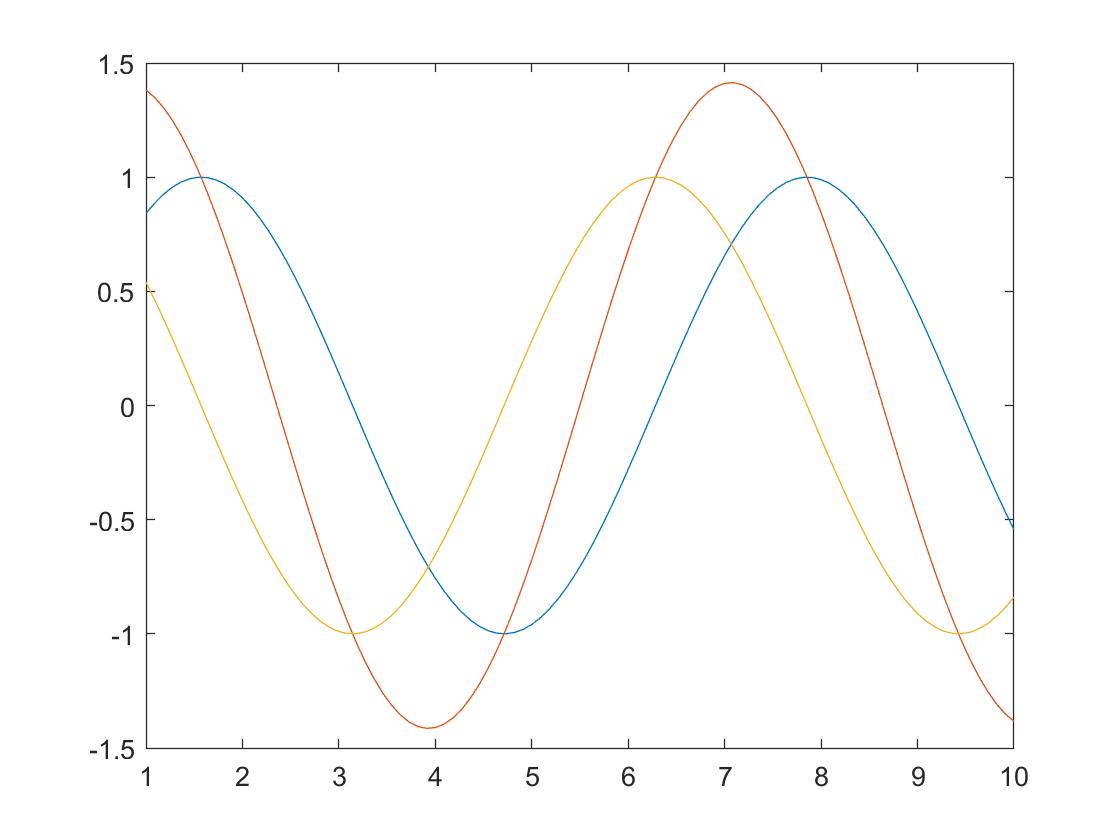

plot(X, y, X, z, X, w)

### Using the hold on and hold off Commands

- one graph is plotted first using the plot command

- --> start block with hold on command to keep the first plot open

- --> add additional plots

- --> end with hold off command

- without invoking hold on, hold off, the next time plot is called, will reset plot properties

plot(X, y)
hold on
plot(X, z)
plot(X, w)
hold off

#### Using the line Command

- can be used to add graphs (lines) to already existing plots

- line(X, y, 'PropertyName', PropertyValue)

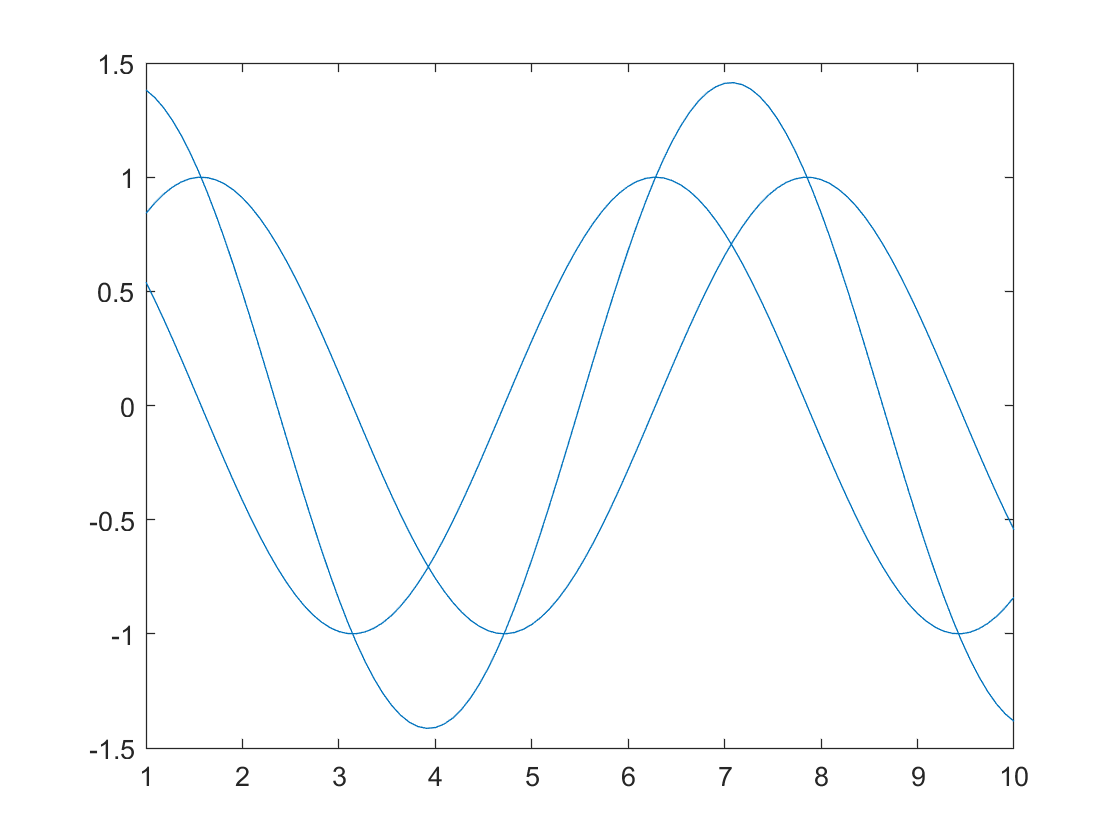

plot(X, y)
line(X, w)
line(X, z)

## Formatting a Plot

- through commands that follow the plot or fplot commands

### Commands

#### The xlabel and ylabel Commands

- placing labels next to the axes

- xlabel('text')

- ylabel('text')

#### The title Command

- adding title to plot

- title('text')

#### The text Command

- placing text label in plot using text or gtext commands

- text(x, y, 'text')

- gtext('text') --> indicate position with the mouse

#### The legend Command

- legend('string1', 'string2', ..., pos)

- --> order of strings corresponds to order in which the graphs were created

- --> pos is an optional number that specifies where in the figure the legend is to be placed

### Formatting Text Within Commands

- can format text using modifier arguments inside string or by adding PropertyName and PropertyValue arguments to the command

- if inside string, can select portion of affected string by inserting it inside {} after the modifier

### The axis Command

- can choose domain and range of plot

- axis([xmin, xmax, ymin, ymax])

### The grid Command

- grid on - adds grid lines to plot

- grid off - removes grid lines

## Plot Commands

### Logarithmic Axes

- semilogy(x, y) - where x is linear and y is logarithmic (base 10)

- semilogx(x, y) - where y is linear and x is logarithmic (base 10)

- loglog(x, y) - logarithmic (base 10) for both axes

### Error Bars

- errorbar(x, y, e) - e is the vector with value of error at each point

- errorbar(x, y, d, u) - d is the vector with the upper-bound errors, while u is lower bound

### Special Graphics

- bar(x, y) - vertical bar plot

- barh(x, y) - horizontal bar plot

- stairs(x, y)

- stem(x, y)

- pie(x)

### Histograms

## Multiple Figure Windows

- the figure window opens and displays a plot each time a plot is generated

- --> if already open, a new plot replaces the figure window

- --> can have multiple windows open at a time

- use figure command

- --> figure(n) allows us to choose which is active

plot(X, y)

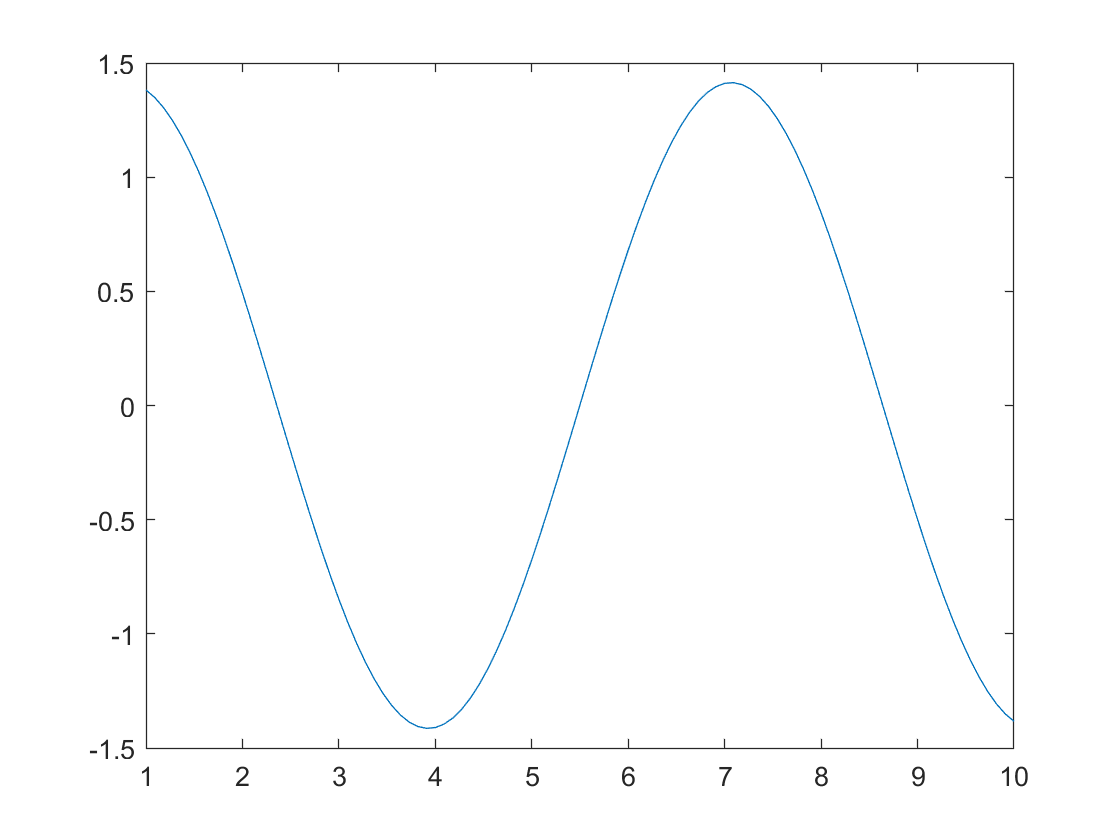

figure
plot(X, z)

### Closing Windows

- close - closes active window

- close(n) - closes the nth window

- close all - closes all Figure windows that are open

# CHAPTER 6 - Programming in MATLAB

## Relational and Logical Operators

### Relational Operators

- < - less than

- > - greater than

- <= - less than or equal to

- >= - greater than or equal to

- == - equal to

- ~= - not equal to